# **변경사항**

**2022.01.25**

- `readVerticalWithoutTime` 추가

# **channerReader의 파일 유형별 read 함수 정리**

- `readBrainSingleChannel`

- `readRetinaWithoutTime`

- `readRetinaWithTime`

- `readMultiChannelFile`

- `readVerticalWithoutTime`

reader_LEGACY = channelReader(); % reader object 생성
reader_NEW = channelReader(); % reader object 생성

## `1. readBrainSingleChannel`

`MEA data.xlsx`와 같은 포맷

                - **3**번째 row부터 데이터 시작

                - row number가 써 있음

                - channel number가 써 있으나 chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있음

%                                           filename, organoid, channel, month 
test_1_LEGACY = reader_LEGACY.LEGACY_readBrainSingleChannel("./data/MEA data.xlsx", 1, 1, 1);
                                      
                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate   organoidNum   channelNum     month
test_1_NEW = reader_NEW.readSingleChannel("./data/MEA data.xlsx", 6,      3,             7,            0,           1,              38,            1);

x =     3.0000       NaN   38.0000         0   30.1990   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    4.0000       NaN   38.0000         0   30.2829    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0

x =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0

다음 사용 중 오류가 발생함: resample
3번째 입력 인수 Fs은(는) 양수(positive)이어야 합니다.

오류 발생: resample>validateFs (842번 라인)
validateattributes(fs, {'numeric'},{'real','finite','scalar', ...

오류 발생: resample>nonUniformResample (285번 라인)
    validateFs(fs);

오류 발생: 

            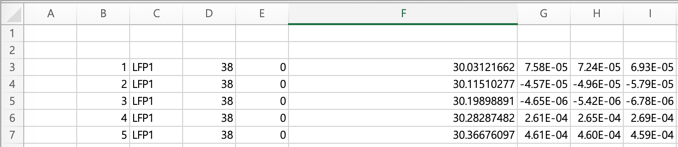

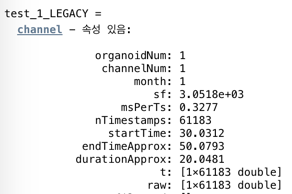         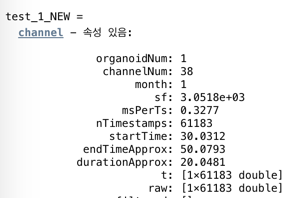

## `2. readRetinaWithoutTime`

`Data 1.csv`와 같은 포맷

                - **8**번째 row부터 데이터 시작

                - channel number 써 있지 않음, chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있지 않음

                        - 시작 시간을 알 수 없음 -> 0초에서 시작한 것으로 간주

                        - 각 row의 duration을 알 수 없음 -> sampling rate 정보 필요

%                                      filename, sampling rate(HZ), organoid, channel, month
test_2_LEGACY = reader.LEGACY_readRetinaWithoutTime("./data/Data 1.csv", 3152, 1,1,1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.



                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_2_NEW = reader.readSingleChannel("./data/Data 1.csv",      0,       8,             1,            3152,           1,              1,            1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.


            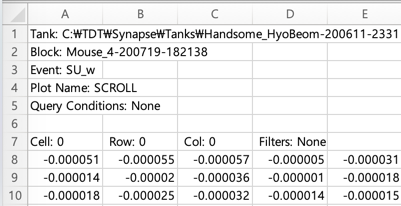

     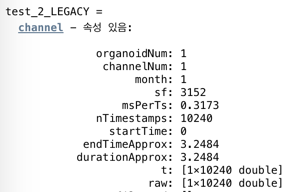         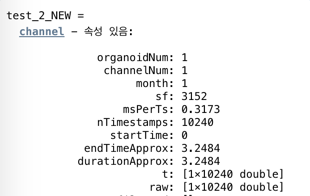

## `3. readRetinaWithTime`

`Data 2.csv`와 같은 포맷

                - **8**번째 row부터 데이터 시작

                - channel number 써 있지 않음, chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있음

%                                      filename, organoid, channel, month
test_3_LEGACY = reader.LEGACY_readRetinaWithTime("./data/Data 2.csv", 1,1,1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
1행의 관측치 수가 1382로, 2048개인 다른 행보다 관측치 수가 적습니다.



                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_3_NEW = reader.readSingleChannel("./data/Data 2.csv",      1,       8,             2,            nan,           1,              1,            1);

파일의 마지막 열이 모두 공백 문자로 되어 있습니다. matlab은 공백 문자를 NaN으로 불러옵니다. 해당 열을 삭제했습니다.
1행의 관측치 수가 1382로, 2048개인 다른 행보다 관측치 수가 적습니다.


            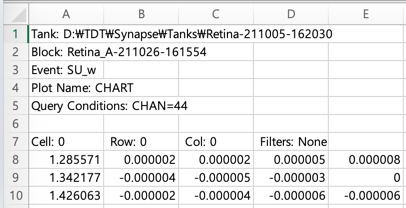

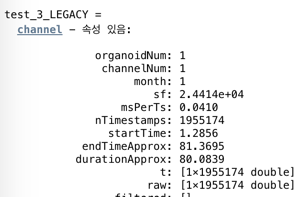      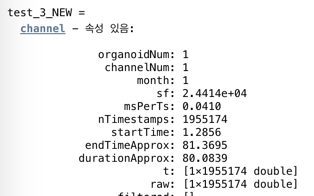

## `4.readVerticalWithoutTime`

`추가 데이터.xlsx `와 같은 포맷

                - 1번째 row부터 데이터 시작

                - channel number 써 있지 않음, chnnel이 하나밖에 없음

                - row마다 시작 시간이 기록되어 있지 않음

                        - 시작 시간을 알 수 없음 -> 0초에서 시작한 것으로 간주

                        - 각 row의 duration을 알 수 없음 -> sampling rate 정보 필요

%                                      filename, sampling rate(HZ), organoid, channel, month
test_4_LEGACY = reader.LEGACY_readVerticalWithoutTime("./data/추가 data.xlsx", 3152, 1,1,1);
                                        % filename,     timeColumnIdx  startRowIdx   startColIdx   sampleRate     organoidNum   channelNum     month
test_4_NEW = reader.readSingleChannel("./data/추가 data.xlsx",      0,       1,             2,            3152,           1,              1,            1);

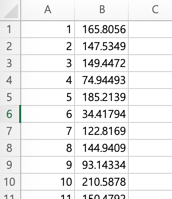

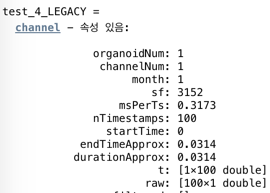     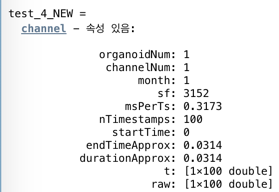

## `5.readMultiChannelFile`

`1_singleunit wave.xlsx, 전체.xlsx `와 같은 포맷

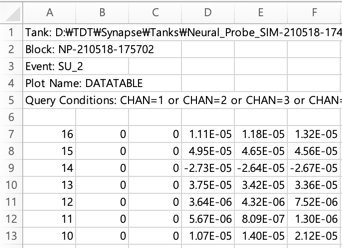     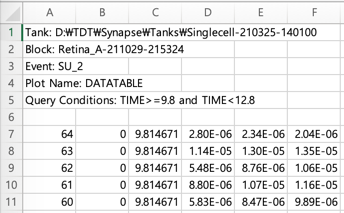

                - **7**번째 row부터 데이터 시작

                - channel number 기록되어 있음, chnnel이 여러 개 있음

                - row마다 시작 시간이 기록되어 있음

`readMultiChannelFile으로 파일 자체를 읽어온 다음, 아래의 두 가지 방법을 사용`

- `readSingleChannelFromFile: ``채널 번호를 특정하여 한 개의 채널의 데이터만 channel object로 만듦`

- `readManyChannelsFromFile: ``여러 채널 번호의 데이터를 channel object로 만듦. channel object의 리스트가 반환되며, {}로 인덱싱하면 개별 channel object가 나옴`

tic 
reader_LEGACY.LEGACY_readMultiChannelFile("./data/전체.xlsx"); %일단 파일을 불러옴

이름 reader_LEGACY.LEGACY_readMultiChannelFile을(를) 확인할 수 없습니다.

toc % 코드 실행 시간 측정. 오래 걸림.

tic 
reader.LEGACY_readMultiChannelFile("./data/전체.xlsx"); %일단 파일을 불러옴
toc % 코드 실행 시간 측정. 오래 걸림.

%                                      organoid, channel, month 
o1_ch8_m1 = reader.readSingleChannelFromFile(1, 8, 1); %8번 채널 데이터를 불러옴

%                                   organoid, array of channel numbers, month 
pixels = reader.readManyChannelsFromFile(1, 1:64, 1);
pixel1 = pixels{1} % 64개 채널 중 첫 번째 채널

ans =   165.8056
  147.5349
  149.4471
   74.9449
  185.2139
   34.4179
  122.8169
  144.9409
   93.1433
  210.5878


ans = 100

ans =          0    0.0003    0.0006    0.0010    0.0013    0.0016    0.0019    0.0022    0.0025    0.0029    0.0032    0.0035    0.0038    0.0041    0.0044    0.0048    0.0051    0.0054    0.0057    0.0060    0.0063    0.0067    0.0070    0.0073    0.0076    0.0079    0.0082    0.0086    0.0089    0.0092    0.0095    0.0098    0.0102    0.0105    0.0108    0.0111    0.0114    0.0117    0.0121    0.0124    0.0127    0.0130    0.0133    0.0136    0.0140    0.0143    0.0146    0.0149    0.0152    0.0155


ans = 100